**2.5 Suppressing Noise Interference Patterns**

Occasionally with poor television reception, parallel lines will be seen on the screen corrupting the desired image. These are interference patterns. Here we explore how bandpass filtering can be used to suppress such interference.

a. Download the image ‘pck-int.jpg’ from edveNTUre and display it from MATLAB. Notice the dominant diagonal lines destroying the quality of the image.

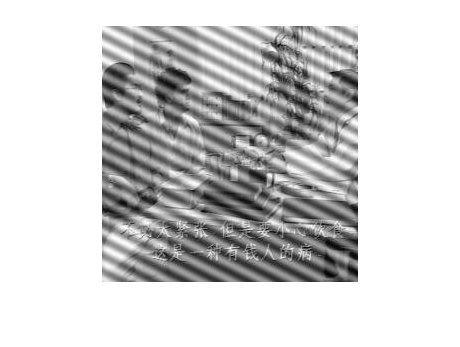

pckInterferenceImage = imread('images/pck-int.jpg');
imshow(pckInterferenceImage);

b. Obtain the Fourier transform F of the image using fft2, and subsequently compute the power spectrum S. Note that F should be a matrix of complex values, but S should be a real matrix.

pckSpectrum = fft2(pckInterferenceImage);

realPart = real(pckSpectrum);
imagPart = imag(pckSpectrum);

% from lecture:
% a + j*b = sqrt(a^2 + b^2) e^(j*phi)
%        = c * e^(j*phi)
% i.e. cartesian -> polar form

% c   - amplitude spectrum
% phi - phase spectrum
% c^2 - power spectrum
powerSpectrum = realPart.^2 + imagPart.^2;

Display the power spectrum by

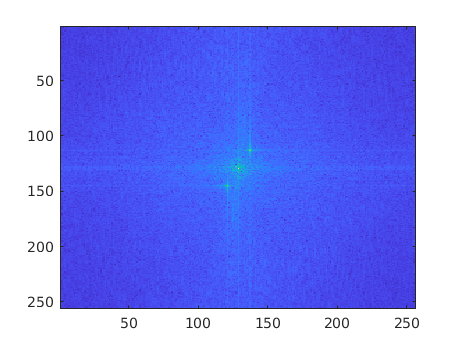

imagesc(fftshift(powerSpectrum.^0.1));
colormap('default');

**fftshift** is used to shift the origin of the Fourier transform to the centre of the image. Note that the origin corresponds to the DC (or zero frequency) component. The power to 0.1 is only used to nonlinearly scale the power spectrum such that it is easier to visualize the frequency components.

Notice that there are two distinct, symmetric frequency peaks that are isolated from the central mass. These frequency components correspond to the interference pattern.

c. Redisplay the power spectrum without **fftshift**. Measure the actual locations of the peaks. You can read the coordinates off the x and y axes, or you can choose to use the **ginput** function.

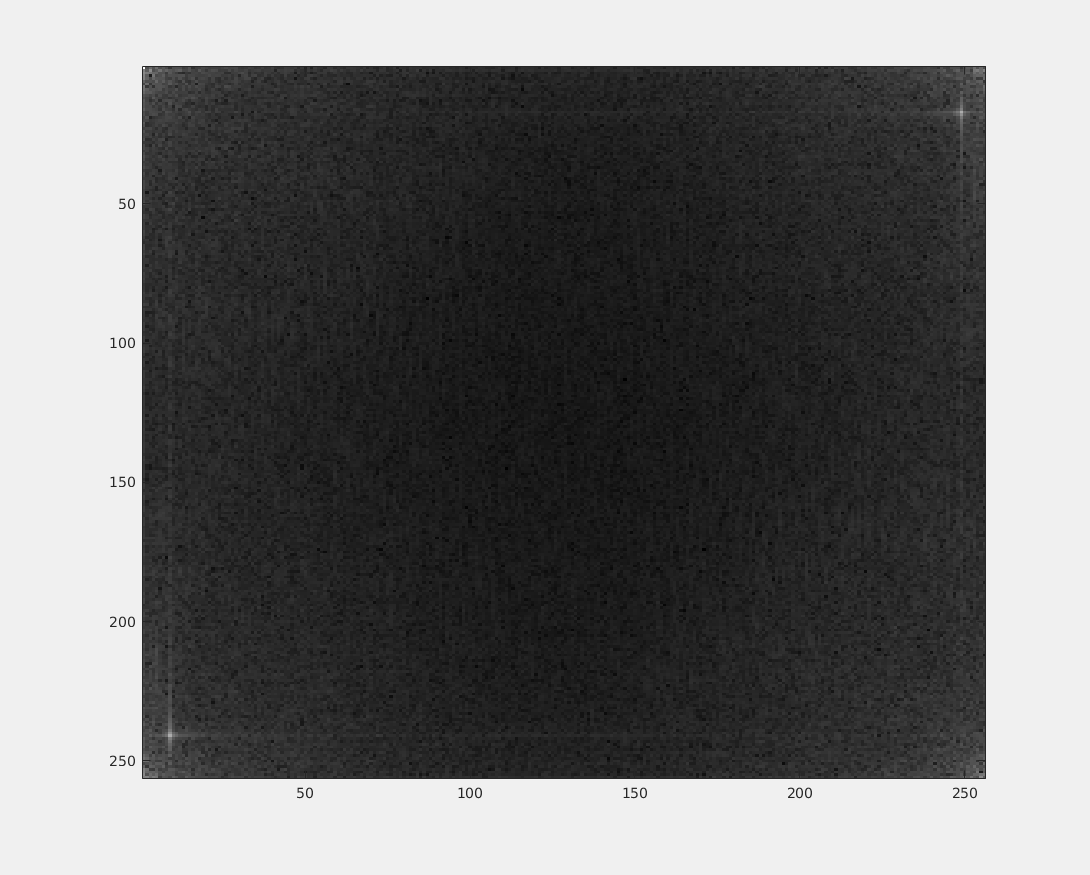

X =   249.0687
    8.8412


Y =    16.8366
  240.5224


imagesc(powerSpectrum.^0.1);
colormap('gray');
[X, Y] = ginput(2)

d. Set to zero the 5x5 neighbourhood elements at locations corresponding to the above peaks *in the Fourier transform F*, not the power spectrum. Recompute the power spectrum and display it as in step (b).

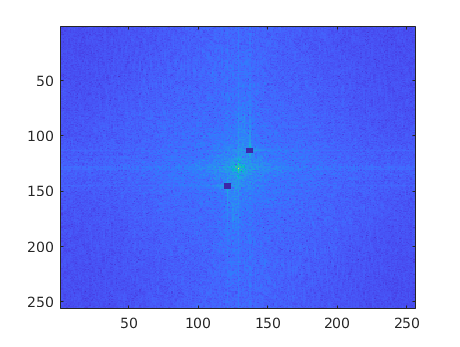

X = round(X);
Y = round(Y);

pckSpectrum(Y(1)-2: Y(1)+2, X(1)-2: X(1)+2) = 0;
pckSpectrum(Y(2)-2: Y(2)+2, X(2)-2: X(2)+2) = 0;

realPart = real(pckSpectrum);
imagPart = imag(pckSpectrum);

powerSpectrum = realPart.^2 + imagPart.^2;

imagesc(fftshift(powerSpectrum.^0.1));
colormap('default');

e. Compute the inverse Fourier transform using **ifft2** and display the resultant image. Comment on the result and how this relates to step (c). Can you suggest any way to improve this?

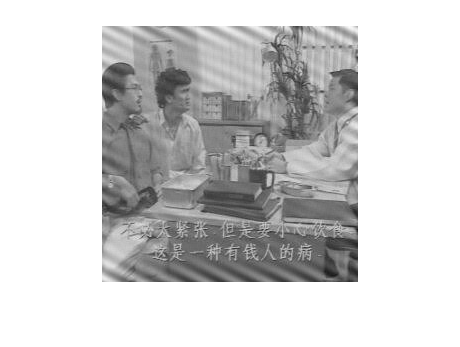

pckDenoisedImage = ifft2(pckSpectrum);
imshow(uint8(pckDenoisedImage));

comment on result: interference can still be seen (it is just more faint)

how this relates to step (c): TODO

way to improve this: 

- increase area of removal from 5x5 to 15x15

- interference appear to not just be 2 regions, but lines in both X and Y direction that originates from the 2 points

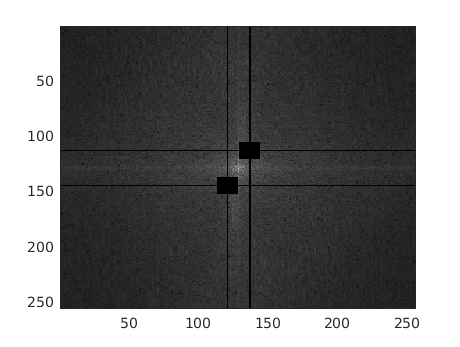

pckNewSpectrum = fft2(pckInterferenceImage);

pckNewSpectrum(Y(1)-7: Y(1)+7, X(1)-7: X(1)+7) = 0;
pckNewSpectrum(Y(2)-7: Y(2)+7, X(2)-7: X(2)+7) = 0;

pckNewSpectrum(Y(1), :) = 0;
pckNewSpectrum(:, X(1)) = 0;
pckNewSpectrum(Y(2), :) = 0;
pckNewSpectrum(:, X(2)) = 0;

realPart = real(pckNewSpectrum);
imagPart = imag(pckNewSpectrum);

powerSpectrum = realPart.^2 + imagPart.^2;
imagesc(fftshift(powerSpectrum.^0.1));
colormap('gray');

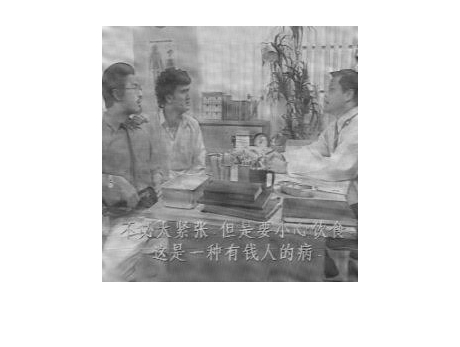


pckImprovedImage = ifft2(pckNewSpectrum);
imshow(uint8(pckImprovedImage));

f. Download the image `primate-caged.jpg’ from edveNTUre which shows a primate behind a fence. Can you attempt to “free” the primate by filtering out the fence? You are not likely to achieve a clean result but see how well you can do.

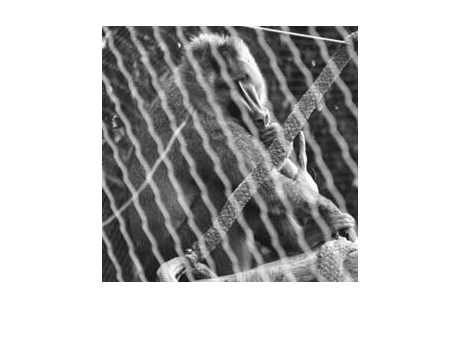

cagedPrimateImage = imread('images/primate-caged.jpg');
imshow(cagedPrimateImage);


cagedPrimateSpectrum = fft2(cagedPrimateImage);

realPart = real(cagedPrimateSpectrum);
imagPart = imag(cagedPrimateSpectrum);

powerSpectrum = realPart.^2 + imagPart.^2;

uint8(powerSpectrum)

ans = 256×256×3 uint8 array
ans(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

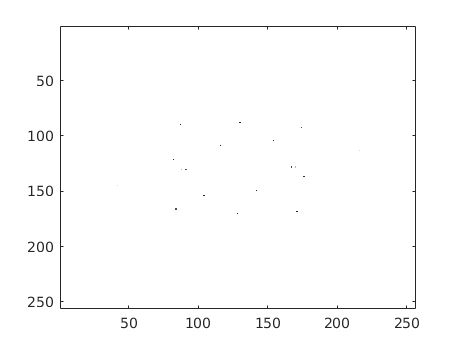

imagesc(uint8(powerSpectrum));
colormap('gray');